# Illustration of unit root tests

In this tutorial, we study how to choose the appropriate test given the nature of the data. 

(adapted from the Matlab help file entry "Unit Root Tests". Explore this file and the other related examples for further exercise)

## Augmented Dickey Fuller tests

### Choice of test

Dickey and Fuller suggest three different potential test equations (with different critical values):


$$\triangle y_t = \gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $$



$$\triangle y_t = a_0 +\gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $$



$$\triangle y_t = a_0 + a_2 t +\gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $$


Which do we use? Do we just test $H_0: \gamma=0$? Or should we consider joint hypothesis?

One could start from the most general (the third equation), but Enders warns against this: it has more parameters to estimate, hence lower degrees of freedom, which implies that the confidence intervals for the unit root test ($H_0: \gamma=0$) are much wider when drift and/or trend terms are included. 

The best practice is to use common sense and economic reasoning to choose the correct type of test. 

Matlab's implementation of the Augmented Dickey Fuller test makes this very simple, although you need to read the help file carefully (as you should do with each and every method you intend to use - *assuming* you know what a command/function does is a recipe for disaster)

The general syntax is:

The five possible tests specifications are: 

#### Specification 1:

        The *'model','AR'* specification imposes that $a_0=a_1=0$ (no constant, no time trend in test equation)

        The *'test', 't1' *specification tests the null $H_0: \gamma=0$, i.e.

        $\triangle y_t = \sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $ , ($y_t$ is a random walk without drift)

        against the alternative $H_a: \gamma<0$, i.e.

        $\triangle y_t = \gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $, ($y_t$ is a stationary ARMA process without constant)

#### Specification 2:

        The *'model','ARD'* specification allows $a_0\neq0$ but imposes that $a_2=0$ (a constant, but no time trend in test equation)

        The *'test', 't1' *specification tests the null $H_0: \gamma=0$, i.e

        $\triangle y_t = a_0 +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $, ($y_t$ is a random walk with drift)

        against the alternative $H_a: \gamma<0$, i.e.

        $\triangle y_t = a_0+\gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $, ($y_t$ is a stationary ARMA process with constant)

#### Specification 3:

        The *'model','ARD'*  specification allows $a_0\neq0$ but imposes that $a_2=0$ (a constant, but no time trend in test equation)

        The *'test', 'F' *specification tests the joint null $H_0: \gamma=a_0=0$, i.e. 

        $\triangle y_t = \sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $ , ($y_t$ is a random walk without drift)

        against the alternative $H_a: a_0 \neq 0, \gamma<0$, i.e.

        $\triangle y_t = a_0+\gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $ ($y_t$ is a stationary ARMA process with constant)

#### Specification 4:

        The *'model','TS'*  specification allows both $a_0\neq0$ and $a_2\neq0$  (a constant and time trend in test equation)

         The *'test', 't1' *specification tests the null $H_0: \gamma=0$, i.e

        $\triangle y_t = a_0 + a_2 t+\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $, ($y_t$ is a random walk with drift *and *deterministic trend)

        against the alternative $H_a: \gamma<0$, i.e.

        $\triangle y_t = a_0 +a_2 t+\gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $ ($y_t$ is a ARMA process with deterministic trend)

#### Specification 5:

        The *'model','TS'*  specification allows both $a_0\neq0$ and $a_2\neq0$  (a constant and time trend in test equation)

       The *'test', 'F' *specification tests the joint null $H_0: \gamma=a_2=0$, i.e. 

        $\triangle y_t = a_0 + \sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $ , ($y_t$ is a random walk with drift)

        against the alternative $H_a: a_2 \neq 0, \gamma<0$, i.e.

        $\triangle y_t = a_0 +\gamma y_{t-1} +a_2 t+\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $ with$\gamma < 0$ ($y_t$ is a ARMA process with deterministic trend)

*So, how do we choose? *

It depends on the economic nature and observed character of the data. You should go through the formal arguments in all directions when you do your own work - read Enders' discussion carefully. 

My rule of thumb is simple: 

If the process has no obvious trend (or cannot, by economic reason, have a permanent trend - e.g. something like real exchange rates or interest rate spreads), the interesting question is whether it is a random walk without drift, or a stationary arma process. If the process is approximately mean zero, then test 1 is appropriate, otherwise test 3. 

If the data has an obvious, approximately linear trend (and that trend is defensible in economics terms, like GDP or prices), then the interesting question is whether it is a unit root process with drift, or a trend-stationary ARMA process with a deterministic trend. This is test 5.

The other examples are valid statistically, but seem odd to me, as the predicted behaviour under the null and alternative are very different, so would be odd to use as a comparison. For instance, under the null in option 4, the process will have a a stochastic trend AND a quadratic trend in time under the null whereas it has a linear trend under the alternative. 

### Simulated examples

We will illustrate the tests and their interpretation with four simulated series: a stationary but persistent AR process without trend, a random walk without drift, A trend-stationary process, and a random walk with drift.

A key take-away from this example is to see how sensitive the results are to the size of the sample. Try $T=100$ and $T=200$.

#### Generate data 

T = 100;        % Sample size
trend = (1:T)'; % Time trend vector
rng(1234) % For reproducibility 

% Stationary but persistent AR process:
Mdl_AR = arima('AR',0.9,'Constant',0.2,'Variance',3);
y_AR = simulate(Mdl_AR,T);

% Unit root process without drift (with some more complicated AR components)
Mdl_RW = arima('AR',{0.3,0.1,0.4},'D',1,'Constant',0,'Variance',0.15);
y_RW = simulate(Mdl_RW,T);

% A Trend Stationary process (with some more complicated AR components)
Mdl_TS = arima('AR',{0.3,0.1,0.4},'Constant',0.2,'Variance',2);
y_TS = simulate(Mdl_TS,T) + 0.3*trend;

% Unit root process with drift (with some more complicated AR components)
Mdl_RWD = arima('AR',{0.3,0.1,0.4},'D',1,'Constant',0.1,'Variance',0.15);
y_RWD = simulate(Mdl_RWD,T);

Plot the series:

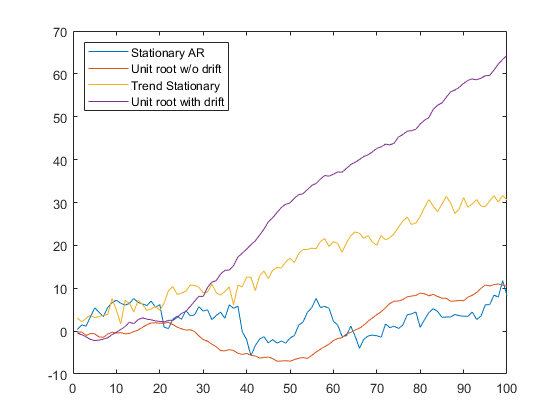

plot([y_AR,y_RW,y_TS,y_RWD]);
    legend('Stationary AR','Unit root w/o drift','Trend Stationary', 'Unit root with drift','location','northwest')

#### Perform the tests

Starting with the first two processes, they obviously have no trend, so we can employ either option 1 or 3. Since they both have constant

**The stationary AR process** 

If the test is accurate, it should *reject *the null of a unit root 

Option 1 (which does not estimate a constant - this affects both the likely fit and the critical values of a test)

[reject,p_value,t_stat,critical_value,regression_output]  = adftest(y_AR,'model','AR','test','t1','lags',0) %#ok<*ASGLU> 

reject = logical
   0


p_value = 0.1125

t_stat = -1.5559

critical_value = -1.9444

regression_output = struct with fields:
       num: 100
      size: 97
     names: {3×1 cell}
     coeff: [3×1 double]
        se: [3×1 double]
       Cov: [3×3 double]
    tStats: [1×1 struct]
     FStat: [1×1 struct]
       yMu: 2.9662
    ySigma: 3.3475
      yHat: [97×1 double]
       res: [97×1 double]
    DWStat: 1.9343
       SSR: 937.8943
       SSE: 291.2831
       SST: 1.2292e+03
       MSE: 3.0988
      RMSE: 1.7603
       RSq: 0.7630
      aRSq: 0.7580
        LL: -190.9906
       AIC: 387.9812
       BIC: 395.7053
       HQC: 391.1044


Option 3 (allow for a constant, but test that both the constant and the gamma coefficient are jointly zero)

[reject,pValue,stat,cValue,reg] = adftest(y_AR,'model','ARD','test','F','lags',0)

reject = logical
   0


pValue = 0.1592

stat = 3.2712

cValue = 4.7157

reg = struct with fields:
       num: 100
      size: 99
     names: {2×1 cell}
     coeff: [2×1 double]
        se: [2×1 double]
       Cov: [2×2 double]
    tStats: [1×1 struct]
     FStat: [1×1 struct]
       yMu: 2.9325
    ySigma: 3.3216
      yHat: [99×1 double]
       res: [99×1 double]
    DWStat: 1.9933
       SSR: 796.7880
       SSE: 284.4432
       SST: 1.0812e+03
       MSE: 2.9324
      RMSE: 1.7124
       RSq: 0.7369
      aRSq: 0.7342
        LL: -192.7281
       AIC: 389.4563
       BIC: 394.6465
       HQC: 391.5562


reg.tStats.pVal

ans =     0.0478
    0.0000


**The unit root process without drift** 

If the test is accurate, it should *not reject *the null of a unit root 

Option 1 (which does not estimate a constant - this affects both the likely fit and the critical values of a test)

[reject,pValue,stat,cValue,reg] = adftest(y_RW,'model','AR','test','t1','lags',3)

reject = logical
   0


pValue = 0.2269

stat = -1.1545

cValue = -1.9444

reg = struct with fields:
       num: 100
      size: 96
     names: {4×1 cell}
     coeff: [4×1 double]
        se: [4×1 double]
       Cov: [4×4 double]
    tStats: [1×1 struct]
     FStat: [1×1 struct]
       yMu: 1.0975
    ySigma: 5.5777
      yHat: [96×1 double]
       res: [96×1 double]
    DWStat: 2.0062
       SSR: 2.9478e+03
       SSE: 12.7899
       SST: 2.9606e+03
       MSE: 0.1390
      RMSE: 0.3729
       RSq: 0.9957
      aRSq: 0.9955
        LL: -39.5078
       AIC: 87.0156
       BIC: 97.2729
       HQC: 91.1618


Option 3 (allow for a constant, but test jointly that both the constant and the gamma coefficient are jointly zero)

[reject,pValue,stat,cValue,reg] = adftest(y_RW,'model','ARD','test','F','lags',3)

reject = logical
   0


pValue = 0.8209

stat = 0.8821

cValue = 4.7213

reg = struct with fields:
       num: 100
      size: 96
     names: {5×1 cell}
     coeff: [5×1 double]
        se: [5×1 double]
       Cov: [5×5 double]
    tStats: [1×1 struct]
     FStat: [1×1 struct]
       yMu: 1.0975
    ySigma: 5.5777
      yHat: [96×1 double]
       res: [96×1 double]
    DWStat: 2.0004
       SSR: 2.9428e+03
       SSE: 12.7284
       SST: 2.9555e+03
       MSE: 0.1399
      RMSE: 0.3740
       RSq: 0.9957
      aRSq: 0.9955
        LL: -39.3011
       AIC: 88.6022
       BIC: 101.4239
       HQC: 93.7849


reg.coeff

ans =     0.0264
    0.9910
    0.4806
   -0.0376
    0.3745


reg.tStats.pVal

ans =     0.5090
    0.0000
    0.0000
    0.7163
    0.0002


**The trend stationary process **

If the test is accurate, it should *reject *the null of a unit root 

Option 5:

[reject,pValue,stat,cValue,reg] = adftest(y_TS,'model','TS','test','F','lags',2)

reject = logical
   0


pValue = 0.3314

stat = 3.8374

cValue = 6.4822

reg = struct with fields:
       num: 100
      size: 96
     names: {6×1 cell}
     coeff: [6×1 double]
        se: [6×1 double]
       Cov: [6×6 double]
    tStats: [1×1 struct]
     FStat: [1×1 struct]
       yMu: 17.2229
    ySigma: 9.0434
      yHat: [96×1 double]
       res: [96×1 double]
    DWStat: 1.9704
       SSR: 7.5854e+03
       SSE: 184.0321
       SST: 7.7694e+03
       MSE: 2.0448
      RMSE: 1.4300
       RSq: 0.9763
      aRSq: 0.9750
        LL: -167.5525
       AIC: 347.1050
       BIC: 362.4911
       HQC: 353.3243


**The random walk with drift process **

If the test is accurate, it should *not* *reject *the null of a unit root 

Option 5:

[reject,pValue,stat,cValue,reg] = adftest(y_RWD,'model','TS','test','F','lags',2)

reject = logical
   0


pValue = 0.3307

stat = 3.8396

cValue = 6.4792

reg = struct with fields:
       num: 100
      size: 97
     names: {5×1 cell}
     coeff: [5×1 double]
        se: [5×1 double]
       Cov: [5×5 double]
    tStats: [1×1 struct]
     FStat: [1×1 struct]
       yMu: 28.7957
    ySigma: 21.0267
      yHat: [97×1 double]
       res: [97×1 double]
    DWStat: 2.0981
       SSR: 4.2421e+04
       SSE: 22.8115
       SST: 4.2444e+04
       MSE: 0.2480
      RMSE: 0.4979
       RSq: 0.9995
      aRSq: 0.9994
        LL: -67.5026
       AIC: 145.0053
       BIC: 157.8789
       HQC: 150.2107
